d = samp_delay([1 10]);
d(2)-d(1);

[pure, Fs] = audioread('sound files\Samuel Kim - Romantic Flight - Cinematic Version.mp3');
[noise1, Fs1] = audioread('sound files\Ollie - Need Someone.mp3');
[noise2, Fs2] = audioread('sound files\Pink Sweat$ - Run Through Fire (drum version).mp3');

% parameters that influence accuracy vs time
min_delay = 120;
max_delay = 1200;
chunk_length = 80e3

chunk_length = 80000


pure = pure( 500e3+(1:40e3*10+max_delay) , :);
noise1 = noise1( 500e3+(1:40e3*10) , :);
noise2 = noise2( 500e3+(1:40e3*10) , :);

mixed = add_delayed_noise(pure, noise1, 500);
mixed = add_delayed_noise(mixed, noise2, 800);

audiowrite('sound files\mixed_matlab_10.wav', mixed, Fs)


beg = mixed(1: min_delay-1, :);
mixed = mixed(min_delay:end, :);
suppressed = mixed;

num_bins = max_delay - min_delay;
noise = [zeros(num_bins, 2); noise1+noise2];

pure_chunk = pure(1:chunk_length, :);

tic
max_i = floor((length(noise)-chunk_length-num_bins) / chunk_length)

max_i = 4

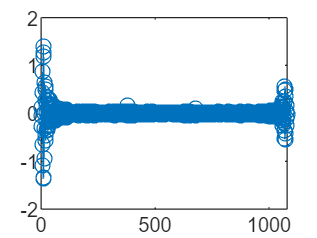

for i = 0:max_i
    mixed_chunk = mixed((1:chunk_length) + i*chunk_length, :);
    noise_chunk = noise((1:chunk_length+num_bins) + i*chunk_length, :);
    suppressed((1:chunk_length) + i*chunk_length, :) = suppress_mixed(mixed_chunk, noise_chunk, num_bins);
end

t = toc

t = 17.8270


suppressed = [beg; suppressed];

fullmixed = [beg; mixed];
corrs = corrcoef(fullmixed, suppressed);
pre_corr = corrs(2, 1);
corrs = corrcoef(suppressed, pure);
corr = corrs(2, 1);
filename = 'T_ECA.csv';
if exist(filename) == 2
    T_ECA = readtable(filename);
    T_ECA = [T_ECA; {chunk_length, corr, pre_corr, t}];
else
    T_ECA = table(chunk_length, corr, pre_corr, t);
end
writetable(T_ECA, filename);
save T.mat T_ECA

audiowrite('sound files\suppressed.wav', suppressed, Fs)

function mixed = add_delayed_noise(mixed, noise, delay)
    range = delay:delay+length(noise)-1;
    mixed(range, :) = mixed(range, :) + noise/4;    % noise is attenuated in mixed signal
end

function suppressed = suppress_mixed(mixed, noise, num_bins)
    suppressed = zeros(size(mixed));
    for ch = 1:2
        n = noise(:, ch); 
        m = mixed(:, ch);

        N = zeros(length(m), num_bins); 
        for col = 1:1:num_bins
            N(:, col) = n( (num_bins+1:length(n)) -col);  % operation takes long if N rows not enough
        end
    
        R = N.'*N;
        p = N.'*m;
        
        x = R\p;
        stem(x)
        suppressed(:, ch) = m - N*x; 
    end
end

function T = write_table(suppressed, pure, T, algorithm)
    corrs = corrcoef(suppressed, pure);
    corr = corrs(2, 1);
    
    T = [T; {algorithm, t, corr}];
    writetable(T);
end

function sd = samp_delay(dist_delay)
    td = dist_delay/343;
    sd = td * 44e3;
end

function x = xCG(R, p)
    num_bins = length(p);
    x = zeros(num_bins, 1);
    r = p - R*x;
    d = r;
    x_arr = [];
    for i = 1:num_bins
        alpha = (d'*r)/(d'*R*d);
        x = x + alpha*r;
        x_arr = [x_arr x];
        
        r_prev = r;
        r = r - alpha*R*r;  % not sure how this is more effecient
        beta = (r'*r)/(r_prev'*r_prev);
        d = r + beta*d;
    end
end

function x = xGradDesc(R, p)
    num_bins = length(p);
    x = zeros(num_bins, 1);
    gradient = 1;
    while abs(gradient) > 10e-6
        gradient = R*x - p; % dC/dx
        alpha = (gradient.'*gradient)/(gradient.'*R*gradient);
        x = x - alpha*gradient;
    end
end